# 論文の実装~Algorithm 2~

## MATLABの初期化処理

clear all;

## システムのダイナミクス


A = [-1 2; 2.2 1.7];
B = [2; 1.6]

B =     2.0000
    1.6000


C = [1 2];

sys = ss(A, B, C, [], 1)


sys =
 
  A = 
        x1   x2
   x1   -1    2
   x2  2.2  1.7
 
  B = 
        u1
   x1    2
   x2  1.6
 
  C = 
       x1  x2
   y1   1   2
 
  D = 
       u1
   y1   0
 
サンプル時間:  1 seconds
離散時間状態空間モデル。



% step(sys)

## 学習パラメータ

F = -1;
Q = 6;
R = 1;
gamma = 0.8;
learningFreq = 21;

K_0 = [0.3 1.3 0.75];
x_0 = [5; -5];
r_0 = [5];
X_0 = [x_0; r_0];

## その他変数宣言

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];
Q1 = C1'*Q*C1;

## 学習

% 初期化
X = X_0;
X_old = X_0;
K1 = K_0;

XExp = [];
count = 0;

yList = [C*x_0];
rList = [r_0];


for i = 1 : 60*21
    % 方策評価
    XExp = [XExp X];
    if (size(XExp, 2) == learningFreq + 1)
        for j = 1 : size(XExp, 2) - 1
            h1 = computeQuadraticBasis(XExp(:, j));
            h2 = computeQuadraticBasis(XExp(:, j+1));
            
            hBuffer(:, j) = h1-gamma*h2;
            yBuffer(:, j) = XExp(:, j)'*(Q1+K1'*R*K1)*XExp(:, j);
        end

        if (rank(hBuffer*hBuffer') <= size(hBuffer, 1)/2)
            disp('rank落ちしています');
        else
%             theta = (hBuffer*hBuffer')\hBuffer*yBuffer';
%             theta = pinv(hBuffer)*yBuffer';
%             theta = lsqminnorm(hBuffer', yBuffer', 'warn');
            theta  =linsolve(hBuffer', yBuffer');
            P_hat = zeros(size(X, 1));
    
            idx = 1;
            for j = 1 : size(X, 1)
                for k = j : size(X, 1)
                    P_hat(j, k) = theta(idx);
                    idx = idx + 1;
                end
            end
            P = (P_hat+P_hat')/2;
        end
        
        % 方策改善
        K1 = (R+gamma*B1'*P*B1)\gamma*B1'*P*T;
        
        XExp = [];
    end
    
    % 行動決定
    u = -K1*X;
    
    % 状態遷移
    X = T * X + B1 * u;
    y = C * X(1:2);
    
    r = X(3);
    yList = [yList; y];
    rList = [rList; r];
end

rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています
rank落ちしています


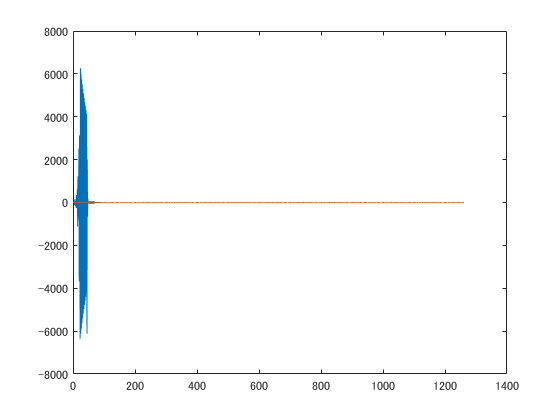


plot(yList);
hold on;
plot(rList);